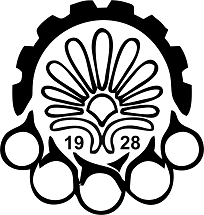

## Amirkabir University of Technology

(Tehran PolyTechnic )

## Turbulence Course Final Project 

Prepared by

## Hossein Sheikhshoaie

Supervisour 

## Dr. Ehsan Tavakoli

Mechanical Engineering Department

2022 spring

[Github code address](https://github.com/Hshsh2391/CFD_final-project/blob/main/H_sheikhsoaie_400126118_final_project.rar)

# Problem specification

Direct numerical solution for fully developed turbulent chnnel flow, between two large horizontal planes with a relatively small Reynolds number (180) based on the frictional velocity ($u_\tau$) and half of the planes distance $\delta
$ has been done. Here some turbulence statistics will be evaluated and visualized. 


$$u_{\tau}\, =\, (\frac{\tau_w}{\rho})^{1/2}$$


## Flow geometry and coordinate system

Streamwise, normal to walls and spanwise direction has been called z, x and y, also their corresponding velocity components are w, u and v, respectively.  

As is evident in underneath figure, planes length and width are $4 \pi,\,2\pi$ respectively. Also channel height is 2. Note that $\delta
$ euals to one. 

128 and 256 nodes have been considered for spanwise and streamwise direction, sequentially.

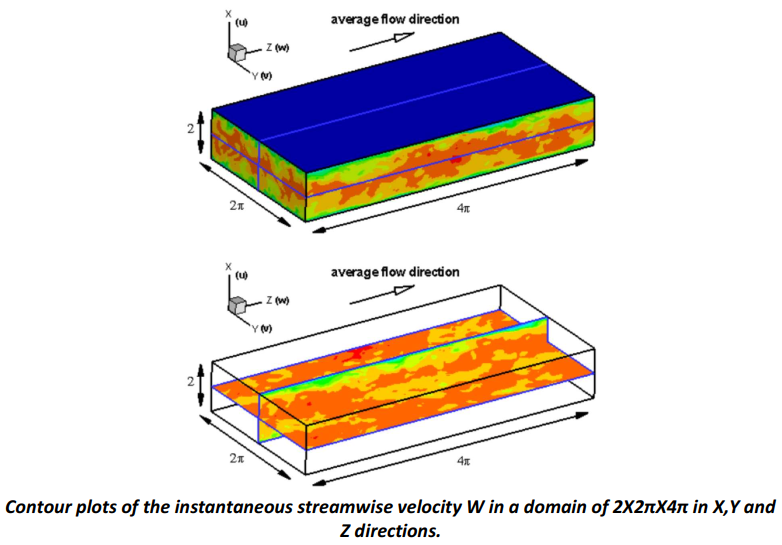

## Data sets

Two data sets are given;

 First is related to temporal records of U,V,W at a point located on the YZ plane which is shown above. 

Second contains spatial records of V and W on a generic YZ planes that is illustrated in the above figure. 

## Project objectives

1) PDFs (single, joint) of the available parameters and try whether you can distinguish

    the resemblance between these PDFs and the famous ones.

2) statistical moments (at least up to third order)

3) correlations (temporal and spatial, auto and cross correlations ,…)

4) Energy spectrum (1D temporal, and 1D-2D spatial)  

clc
clear
close all

# Single PDFs

tab_data = xlsread('UVW_Temporal_Data.xlsx', 'A2:C8193');
u = tab_data(:,1);
v = tab_data(:,2);
w = tab_data(:,3);

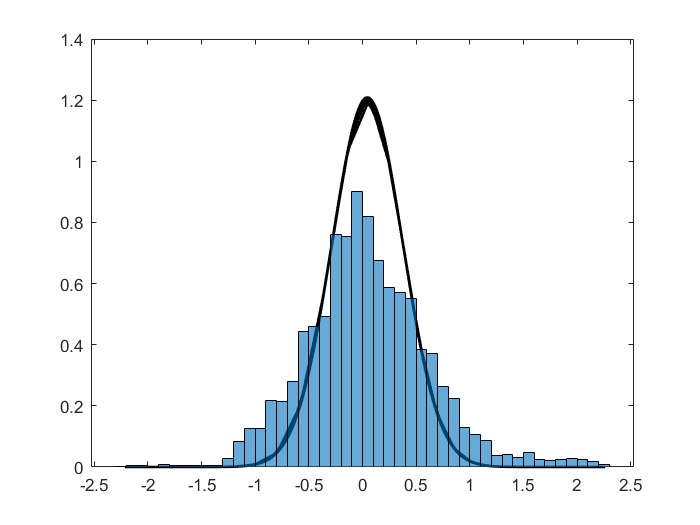

mu_u = mean(u);
sigma_u = var(u);
skewness_u = skewness(u);
kurtosis_u = kurtosis(u);
gauss_u = 1/(sigma_u * sqrt(2* pi)) * exp(-1/2 * ((u - mu_u)/sigma_u).^2);
figure(1)
plot( u , gauss_u  ,'k','linewidth' ,1.5)
hold on
histogram(u,'Normalization','pdf')

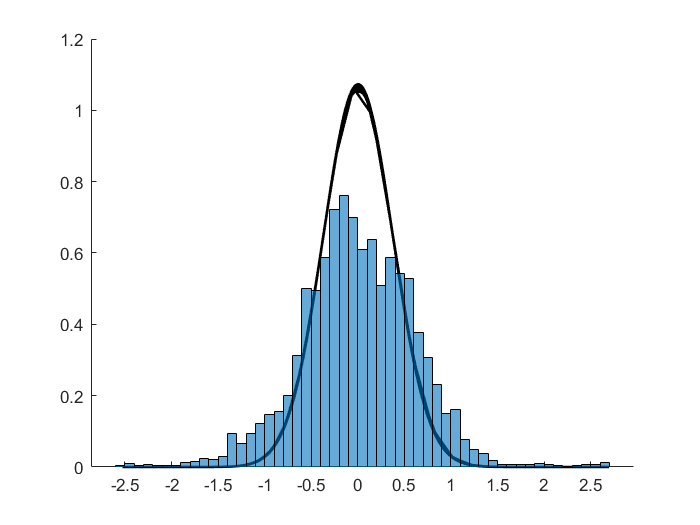

%histogram(u,'Normalization','cdf')
mu_v = mean(v);
sigma_v = var(v);
skewness_v = skewness(v);
kurtosis_v = kurtosis(v);
gauss_v = 1/(sigma_v * sqrt(2* pi)) * exp(-1/2 * ((v - mu_v)/sigma_v).^2);
figure(2)
hold on
plot( v , gauss_v ,'k','linewidth' ,1.5)
histogram(v,'Normalization','pdf')

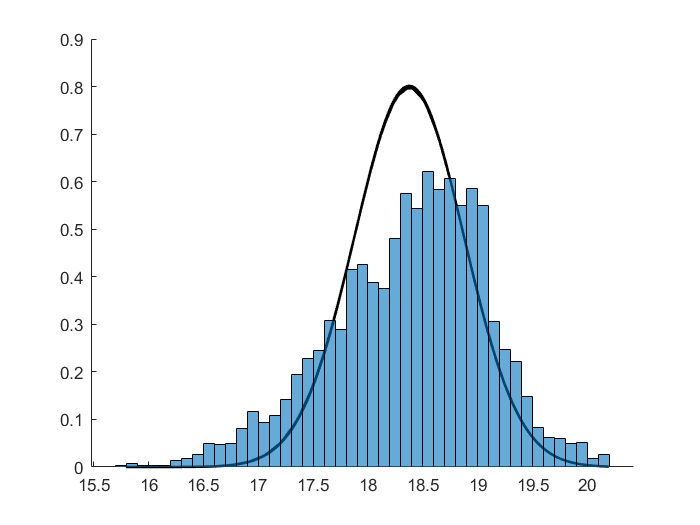


mu_w = mean(w);
sigma_w = var(w);
skewness_w = skewness(w);
kurtosis_w = kurtosis(w);

gauss_w = 1/(sigma_w * sqrt(2* pi)) * exp(-1/2 * ((w - mu_w)/sigma_w).^2);
figure(3)
hold on
plot( w , gauss_w ,'k','linewidth' ,1.5)
histogram(w,'Normalization','pdf')

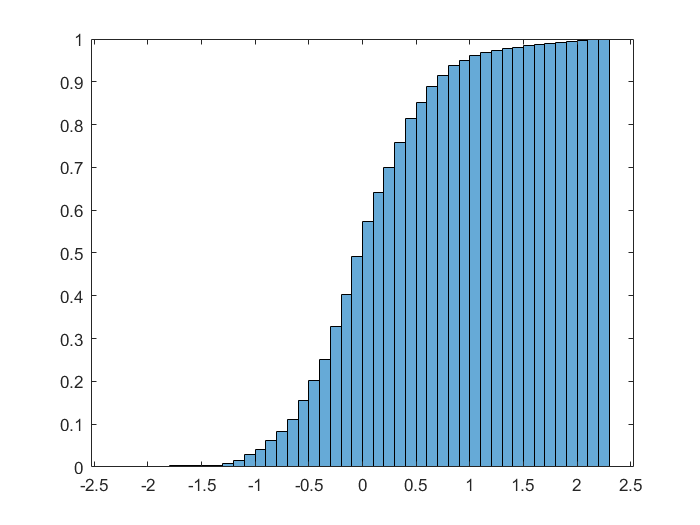

figure(4)
histogram(u,'Normalization','cdf')

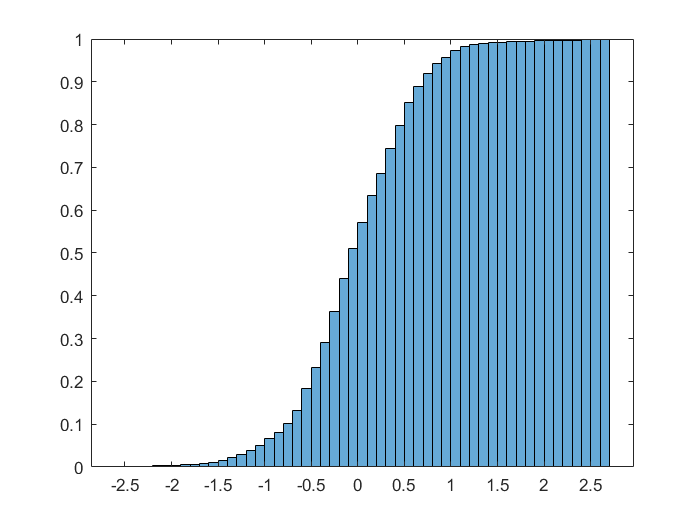

figure(5)
histogram(v,'Normalization','cdf')

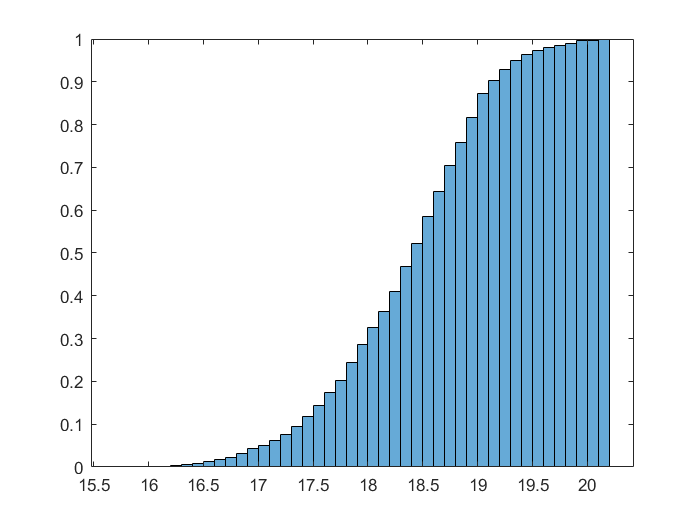

figure(6)
histogram(w,'Normalization','cdf')

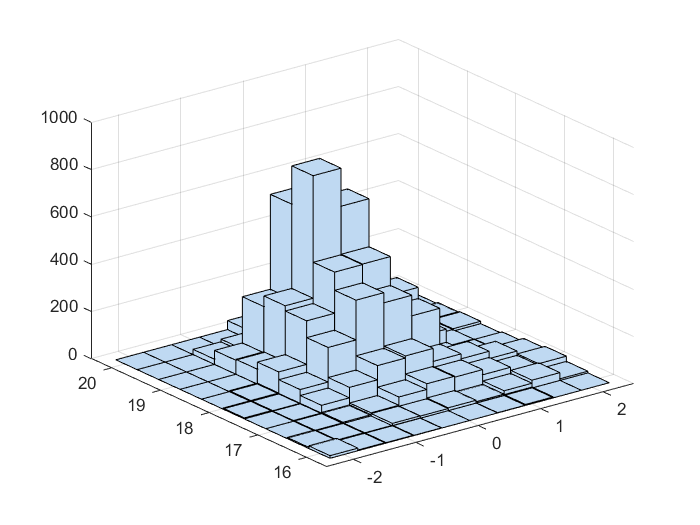

hist3(tab_data(:,1:2:3))

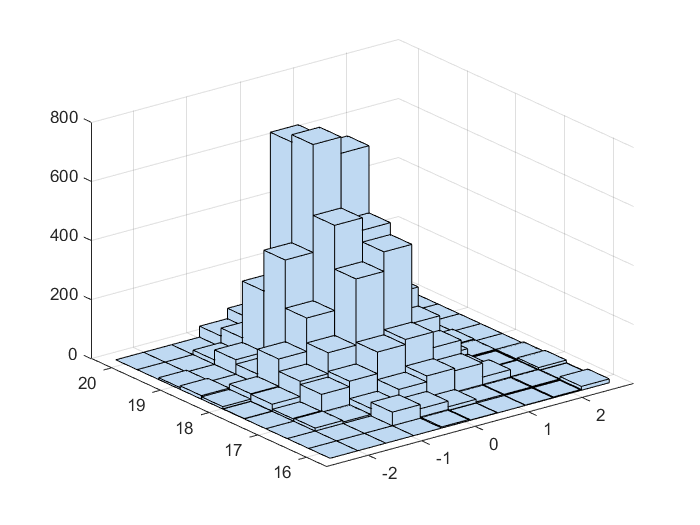

hist3(tab_data(:,2:3))

# Spatial date

## PDFs

tab_data_sp = xlsread('VW_YZ_Spatial_Data.xlsx', 'C3:D32770');
vsp = tab_data_sp(:,1);
wsp = tab_data_sp(:,2);

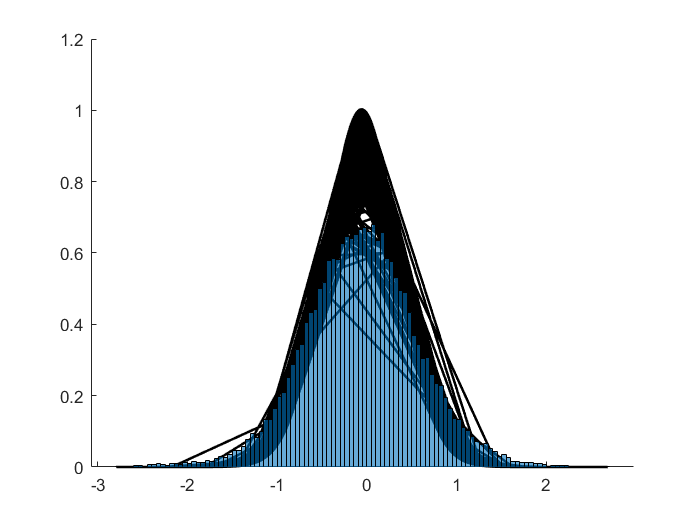

mu_vsp = mean(vsp);
sigma_vsp = var(vsp);
skewness_vsp = skewness(vsp);
kurtosis_vsp = kurtosis(vsp);
gauss_vsp = 1/(sigma_vsp * sqrt(2* pi)) * exp(-1/2 * ((vsp - mu_vsp)/sigma_vsp).^2);
figure(18)
hold on
plot( vsp , gauss_vsp ,'k','linewidth' ,1.5)
histogram(vsp,'Normalization','pdf')

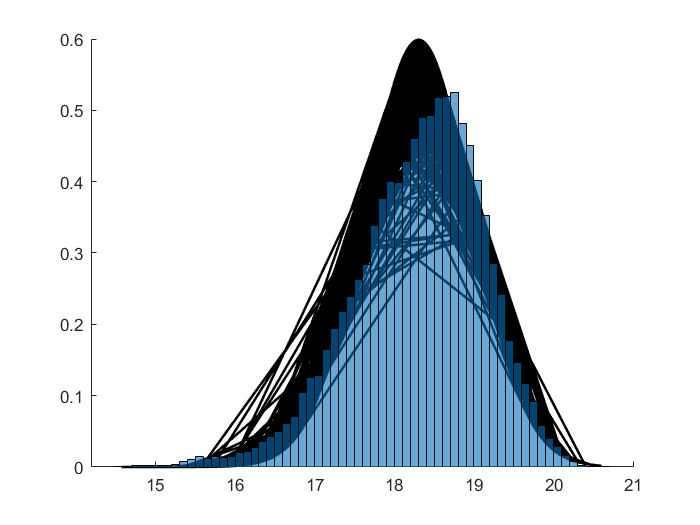

mu_wsp = mean(wsp);
sigma_wsp = var(wsp);
skewness_wsp = skewness(wsp);
kurtosis_wsp = kurtosis(wsp);
gauss_wsp = 1/(sigma_wsp * sqrt(2* pi)) * exp(-1/2 * ((wsp - mu_wsp)/sigma_wsp).^2);
figure(24)
hold on
plot( wsp , gauss_wsp ,'k','linewidth' ,1.5)
histogram(wsp,'Normalization','pdf')

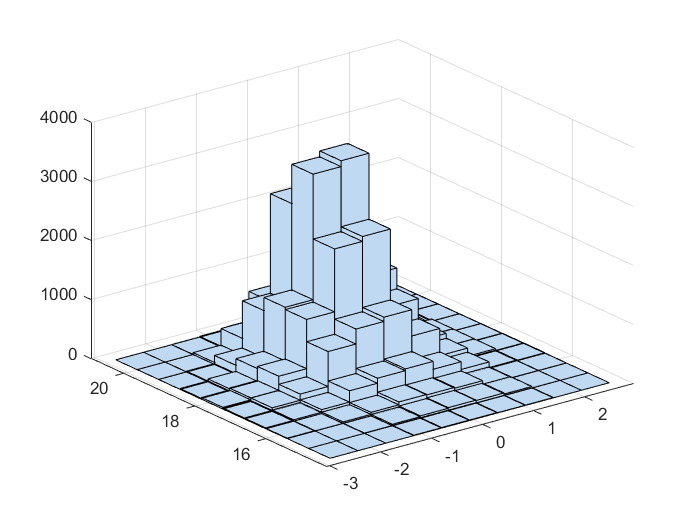

figure(25)
hist3(tab_data_sp(:,1:2))

# Correlations

corrcoef(u - mu_u,v -mu_v)

ans =     1.0000    0.0248
    0.0248    1.0000


corrcoef(w - mu_w,u -mu_u)

ans =     1.0000   -0.1673
   -0.1673    1.0000


corrcoef(w - mu_w,v -mu_v)

ans =     1.0000   -0.1232
   -0.1232    1.0000


%correlation factor tensor
cf_te = [1.0000 -0.1673 -0.1232
    -0.1673    1    0.0248
    -0.1232 0.0248     1  ]

cf_te =     1.0000   -0.1673   -0.1232
   -0.1673    1.0000    0.0248
   -0.1232    0.0248    1.0000


cf_sp = corrcoef(vsp - mu_vsp,wsp -mu_wsp)

cf_sp =     1.0000    0.0009
    0.0009    1.0000


# Reynolds stress tensor

mean ((u - mu_u) .* (v - mu_v))

ans = 0.0087

mean ((w - mu_w) .* (u - mu_u))

ans = -0.0678

mean ((w - mu_w) .* (v - mu_v))

ans = -0.0530

mean ((w - mu_w) .^2)

ans = 0.4978

mean ((u - mu_u) .^2 )

ans = 0.3300

mean ((v - mu_v) .^2)

ans = 0.3717

%Reynolds stress tensor
Re_st_te = [ 0.4978 -0.0678 -0.0530
    -0.0678  0.3300  0.0087
    -0.0530  0.0087  0.3717 ]

Re_st_te =     0.4978   -0.0678   -0.0530
   -0.0678    0.3300    0.0087
   -0.0530    0.0087    0.3717


a = mean((wsp - mu_wsp) .* (vsp - mu_vsp))

a = 4.4925e-04

b = mean((wsp - mu_wsp) .^2 )

b = 0.6661

c = mean((vsp - mu_vsp) .^2 )

c = 0.3978

Re_st_sp = [b a; a c]

Re_st_sp =     0.6661    0.0004
    0.0004    0.3978


# Auto correlation

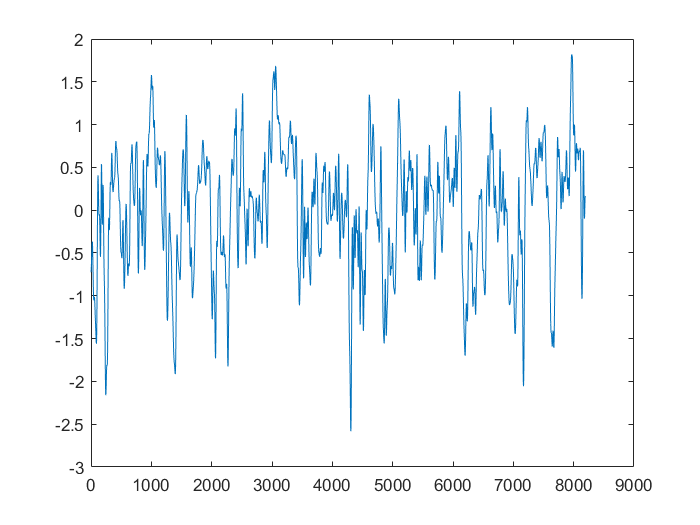

figure(26)
plot(w - mu_w)

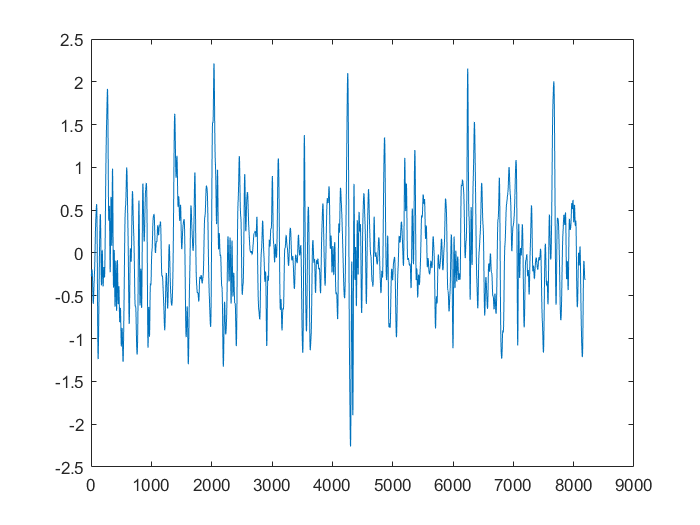

figure(27)
plot(u - mu_u)

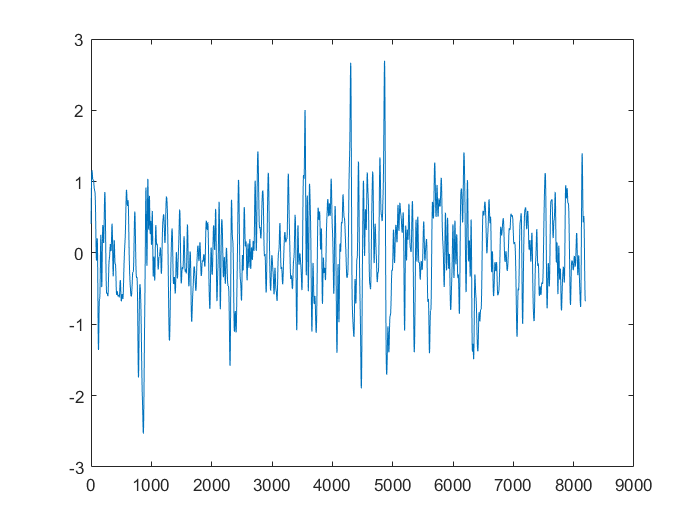

figure(28)
plot(v - mu_v)

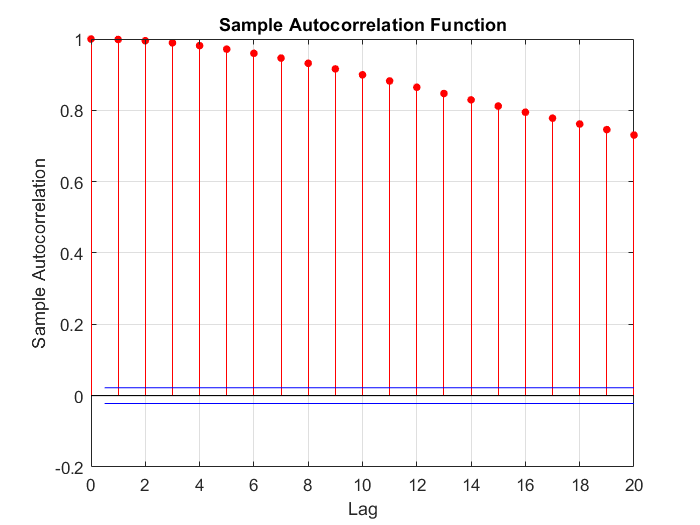

autocorr(w- mu_w)

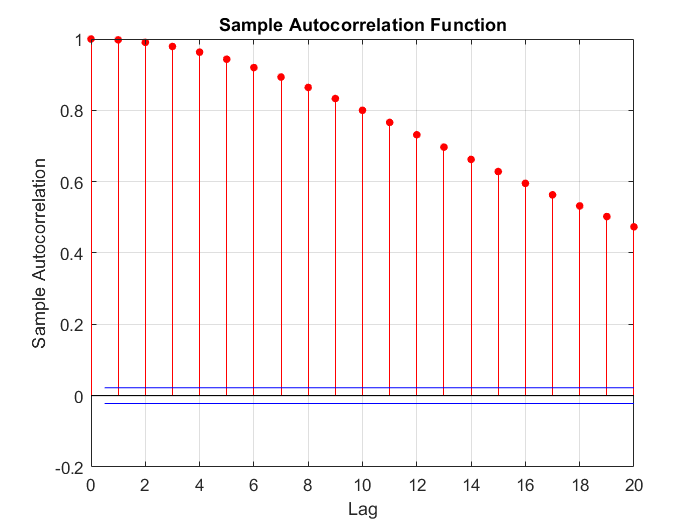

autocorr(u- mu_u)

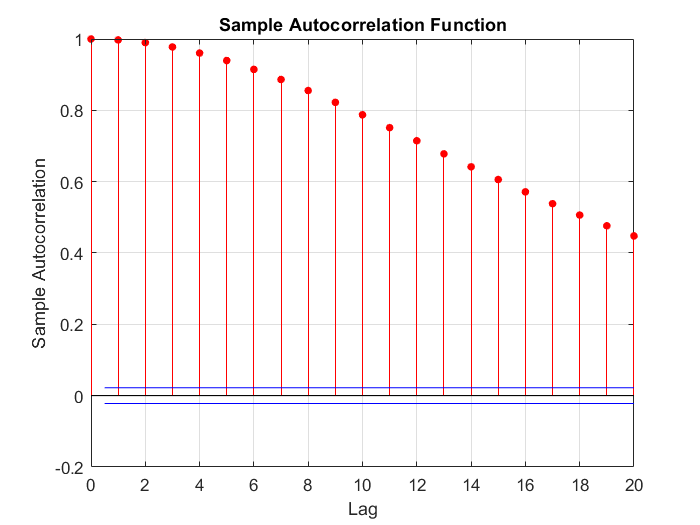

autocorr(v- mu_v)

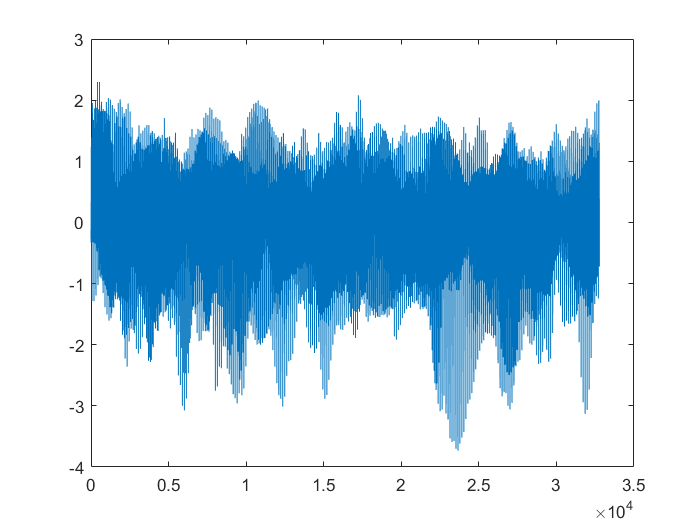

plot(wsp - mu_wsp)

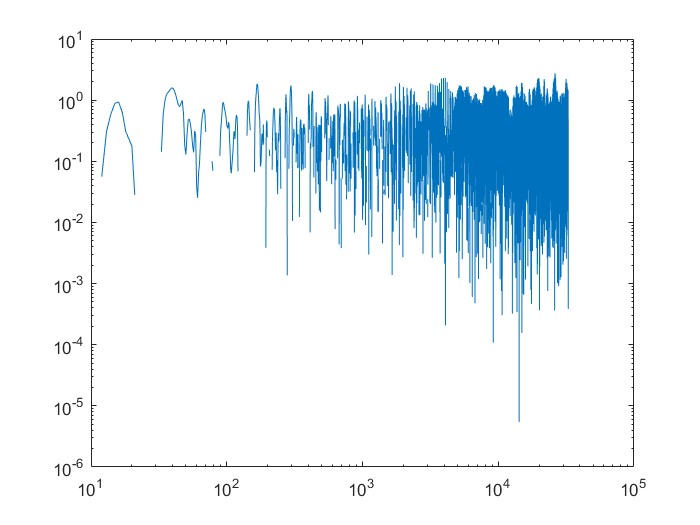

plot(vsp - mu_vsp)

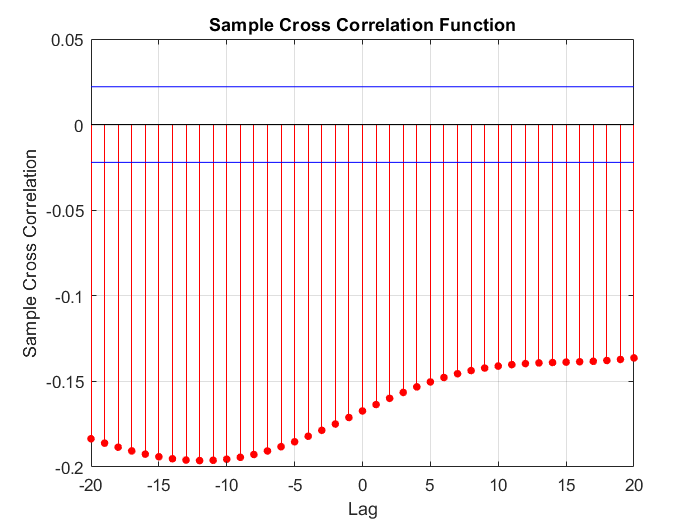

crosscorr(u,w)

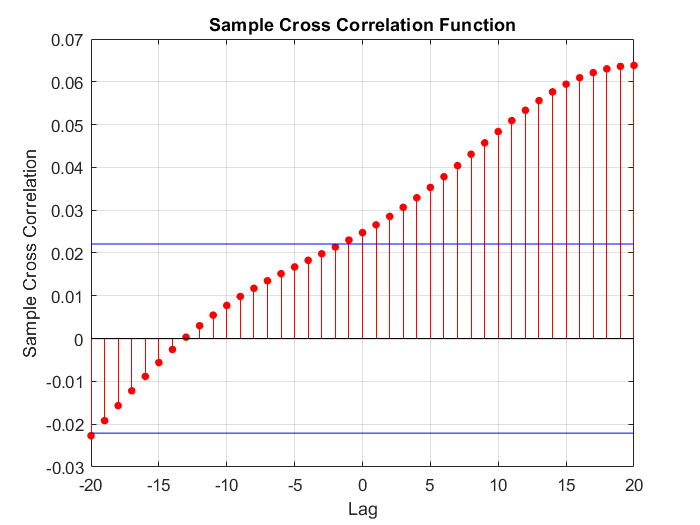

crosscorr(u,v)

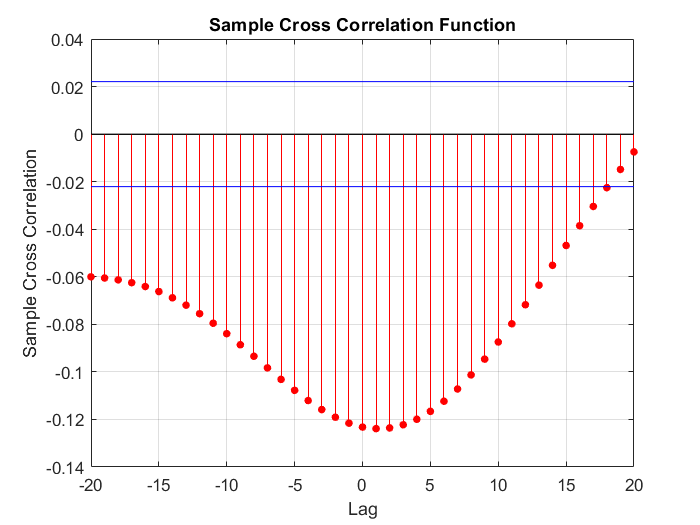

crosscorr(w,v)

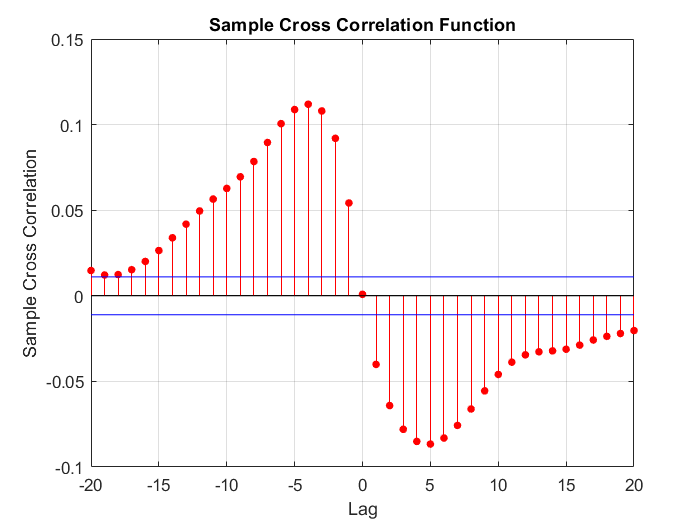

crosscorr(wsp,vsp)

# Energy spectra

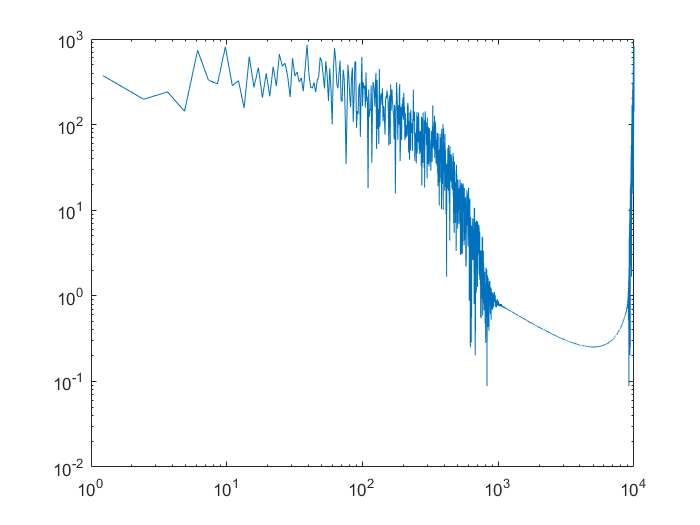

dt=0.0001;% time step
t_final=(8192-1)*dt;
t=0:dt:t_final;
f_max = 1/dt;
df=f_max/(8192-1);
f=0:df:f_max;
figure(35);
loglog(f,abs(fft((w- mu_w) .^2)));

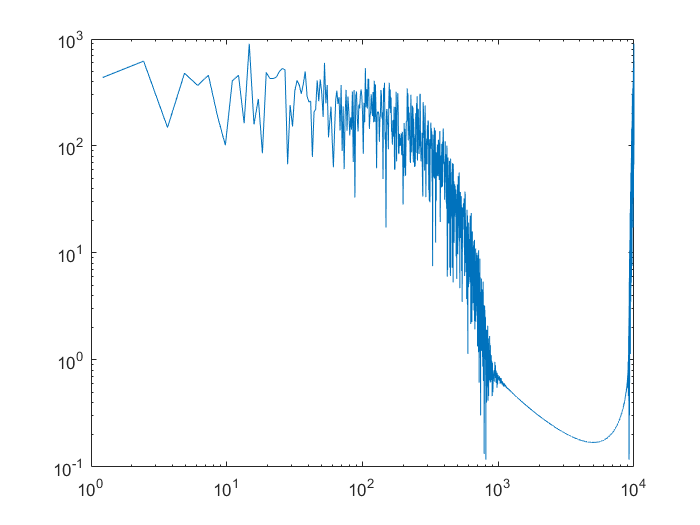

figure(36)
loglog(f,abs(fft((v- mu_v) .^2)));

figure(37)
loglog(f,abs(fft((v- mu_v) .^2)));

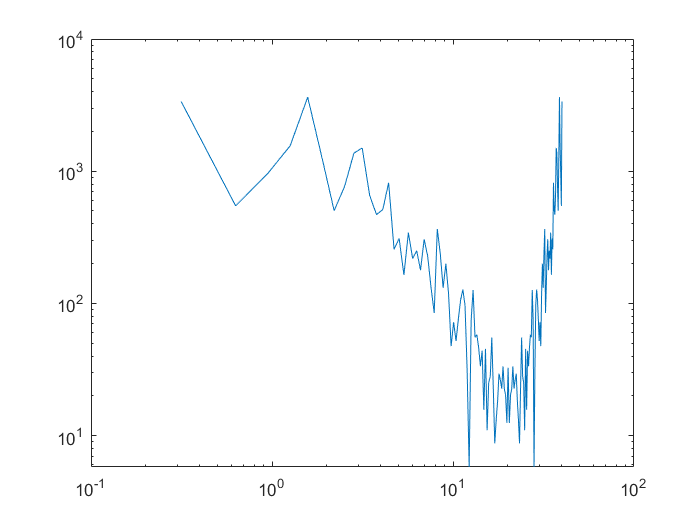

dz= 0.025;
nz = length(vsp)/256;
z = (0:nz -1) * dz;
max_wave_n_z = 1/dz;
dwave_n_z = max_wave_n_z/(nz-1);
wave_n_z = 0: dwave_n_z : 1/dz;
ii=abs(fft((wsp - mu_wsp).^2));
loglog(wave_n_z,ii(1:256:32768,1));

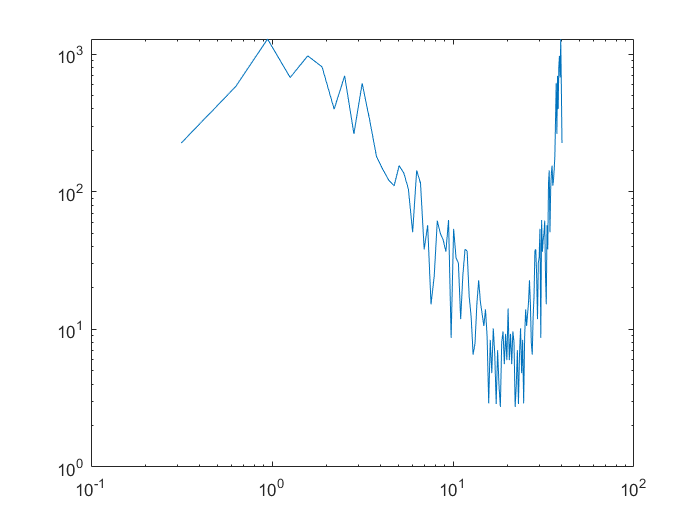

dy = 0.025;
ny = length(vsp)/256;
y = (0:ny -1) * dy;
max_wave_n_y = 1/dy;
dwave_n_y = max_wave_n_y/(ny-1);
wave_n_y = 0: dwave_n_y : 1/dy;
jj=abs(fft((vsp - mu_vsp).^2));
loglog(wave_n_y,jj(1:256:32768,1));

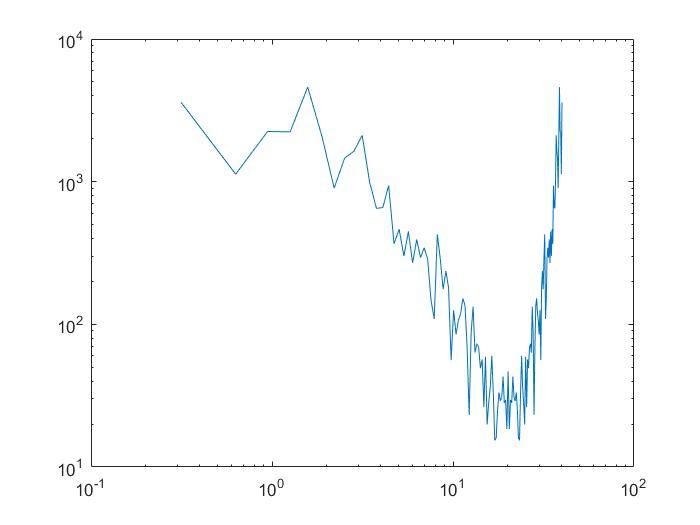

pp = abs(ii) +abs(jj);
dy = 0.025;
ny = length(vsp)/256;
y = (0:ny -1) * dy;
max_wave_n_y = 1/dy;
dwave_n_y = max_wave_n_y/(ny-1);
wave_n_y = 0: dwave_n_y : 1/dy;
jj=abs(fft((vsp - mu_vsp).^2));
loglog(wave_n_y,pp(1:256:32768,1));